**Author: Michael Sacks, Yale University (Senior Undergraduate), F2023**

**Code Research Project for APHY 526**

**This code was written using the functions and documentation of MATLAB R2023a.**

https://chat.openai.com/share/ed5598b0-1b69-450a-856f-8d07d901563f

## **Introduction**

Dynamic optimization finds extensive application across various real-world scenarios where systems evolve over time, requiring adaptive decision-making processes. In the field of finance, dynamic portfolio optimization enables investors to adjust their investment strategies based on changing market conditions.  In healthcare, dynamic optimization supports personalized treatment plans that adapt to the evolving health status of patients. The applications are many and quite varied, but dynamic optimization plays a foundational role in may modern industries.

The Artificial Bee Colony (ABC) algorithm simulates the foraging behavior of bees to solve dynamic optimization problems. The algorithm considers three types of worker bees: employed bees, onlooker bees and scout bees.

## **Real World Context**

This algorithm draws inspiration from the intricate foraging dynamics observed in real beehives. Modeled after the roles of employed, onlooker, and scout bees, this Artificial Bee Colony (ABC) algorithm emulates the collaborative search for optimal solutions in dynamic environments. 

In the bee hierarchy, employed bees venture into the surroundings, exploring for potential food sources. Upon discovery, they communicate this information through intricate dances to onlooker bees awaiting within the hive. The onlookers, equipped with the communicated details, make informed decisions about which food sources to prioritize. Notably, the algorithm mimics the information communicated in a real beehive through nuanced dance variables such as vibration rate and body angle to convey location and food quantity information. Meanwhile, scout bees engage in spontaneous, random searches, contributing to the continuous exploration for new, viable food sources. 

By capturing the essence of these bee behaviors, this algorithm offers an intuitive and effective approach to solving optimization problems, echoing the remarkable efficiency witnessed in the natural world. 

## **Pseudocode for the Algorithm**

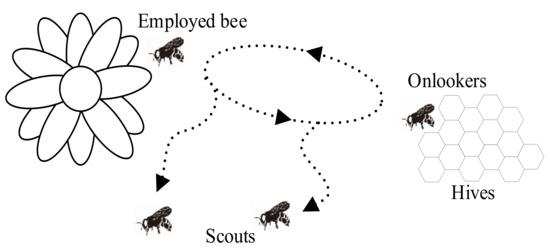

The Artificial Bee Colony (ABC) algorithm simulates the foraging behavior of bees to solve optimization problems. The algorithm considers three roles of bees: employed bees, onlooker bees and scout bees. 

Employed Bees

Employed bees, initially placed at random solutions, iteratively generate nearby candidates according to equation: $v_{ij} = x_{ij} + \phi_{ij}(x_{ij} - x_{kj}),$ where $k \in \{1, 2, \ldots\}$ up to the number of food sources SN and $j \in \{1, 2, \ldots, D\}$} , where D is the dimension of your input function, are randomly chosen indexes. $\phi_{ij}$ is a random number between [-1, 1]. 

They assess the new solution, updating their memory if superior; otherwise, they retain the current solution, increment a count parameter, and transition to a scout role if the count exceeds a predefined limit.

Onlooker Bees

Onlooker bees analyze the fitness of solutions and probabilistically decide which ones to pursue. Solutions with better fitness have a higher probability of being chosen. Probabilities are calculated according to: $p_i = \frac{\text{fit}_i}{\sum_{n=1}^{SN} \text{fit}_n}$ where $\text{fit}_i$ is the fitness value of solution i evaluated by its employed bee [1]. 

The onlooker bee then generates a candidate position using Equation (1). If it improves upon the stored one, the onlooker bee updates its position. If its fitness surpasses that of the employed bee's current position, the employed bee updates its location [2].

Scout Bees

This phase evaluates employed bee solutions by monitoring their cycle count; if the count exceeds a predetermined limit, the solution is discarded, and a new candidate is randomly generated, transforming the employed bee into a scout bee.

Fitness

Fitness represents the quality or suitability of a potential solution to an optimization problem. It is assessed by a fitness function, which quantifies how close the solution aligns with the desired objectives. This function is crucial in the optimization process because it allows us to measure the viability of potential soutions compared to other solutions, guiding our system towards better values. 

Bibliography

[1] D. Karaboga and B. Basturk, Journal of Global Optimization 39, 459 (2007).

[2] Fitness proportionate selection. Wikipedia (2023).

## **ABC Algorithm vs. Other Approaches**

In my eyes, the key strength of the ABC algorithm lies in its intuitive approach modeled from the foraging behavior of honeybees, providing adaptability and efficiency in evolving search spaces. The employed onlooker and scout bee phases enable a dynamic exploration-exploitation balance, crucial in situations where the optimal solution might be constantly changing. The ABC algorithm's simplicity and ease of implementation make it accessible for many applications. Moreover, the algorithm's ability to dynamically adjust its exploration-exploitation trade-off based on the solution landscape boosts its performance. The utilization of global and local search strategies enables effective navigation through complex and time-varying problems. 

## A Note on Runninng the Tutorial:

I recommend running the following code by running each section individually, not all at once. (Click the 'Run Section' button in the Live Editor tab at the top of the screen, NOT the big 'Run' button. The code still functions if you run everything at once, but the tutorial is designed to be run sequentially.)

# **Example 1: Optimizing a test function**

There are three stages in this tutorial. Each goes through different applications of the ABC algorithm. This section walks through optimizing the Rosenbrock function, a single objective, non-constrained test function. 

Rosenbrock function: f(x, y) = (a - x)^2 + b(y - x^2)^2

This function has an analytic solution at: (a, a^2).

## Section 1: Defining the Function

Rosenbrock function:

The 'a' and 'b' parameters determine the behavior of the function. Typically, they are set to: a = 1 and b = 100. Start here and then experiment with different values! 

Some Notes:

- a, b are integers. 

- Let -4 < a < 4 and 0 < b < 500. If you increase them beyond this, you'll have to give the function a wider search space, i.e. alter you lower and upper bounds (see the 'Initialization' section).

Function:

Code:

a = 1;    
b = 100;    

actual_solution = [a, a^2];
rosenbrock = @(x, y) myRosenbrock(x, y, a, b);

## Section 2: Parameters

This section sets the key parameters for the ABC algorithm. There is no explicit 'right' value for any of these parameters. Rather, they are typically found through experimentation. 

Start with the following values, but feel free to come back and change them! Note they must all be positive integers. The starting values are provided to the right of the variables.

A general rule of thumb - the greater your population size 'SN', the more difficult it is to converge to a solution (i.e., 'MCN' and 'limit' must be larger too). A good starting point is setting SN = 20, and MCN to a few hundred, and going from there. Generally, as you have more employed bees you have, you will also explore more solutions at a time. If you set this number too high, many of the solutions won’t be viable and they’ll just be continuously recycled, slowing down the process. For some of the simpler tests, like the Rosenbrock function, this isn’t a big deal, but it can be an issue for more complicated functions.

Note: 20 < SN < 500 and limit = ~ 0.1*MCN is a good rule of thumb for most problems!  If your probelm doesn't converge with the parameters you set, adjust them! If you aren't getting expected fitness values at the end of your iteration limit, try increasing MCN (& limit)! If this still doesn't work, try increasing SN! Repeat until you find the parameters that reliably give a solution.

Code:

SN = 50;        % Size of the population (# of employed and onlooker bees)  % Original: 50
D = 2;          % Number of optimization parameters (System Dimension)      % Original: 2
MCN = 500;      % Maximum Cycle Number (Maximum number of loop iterations)  % Original: 500
limit = 20;     % Number of cycles for food source to be abandoned          % Original: 20

## Section 3: Initialization

This section initializes the solution arrays of the system! Note that there are arrays for both employed and onlooker bees, as well as the fitness of their solutions. We also initialize a count array - this tracks how long each bee has been at their respective 'food source' (solution)!

Note: Nothing needs to be changed here! 

- Unless you choose an 'a'/'b’ value outside the range defined above - then you may need to adjust lower_bound and upper_bound. Note: if you do so, they should remain symmetric (lower_x = lower_y, upper_x = upper_y).

Functions:

Code:

lower_bound = [-16, -16]; % [x_lower, y_lower]                             % Original: [-16, -16]
upper_bound = [16, 16];   % [x_upper, y_upper]                             % Original: [16, 16]
employed_positions = generateFoodSources(SN,lower_bound, upper_bound); 
onlooker_positions = NaN(SN, D);
onlooker_fitness = NaN(SN, D);
count_arr = zeros(SN, 1);
employed_fitness = rosenbrock(employed_positions(:, 1), employed_positions(:, 2));

## Section 4: Optimization Loop

    This loop carries out the ABC algorithm! Each iteration simulates our three phases: employed bees carry out a search of the solution space, onlooker bees favor the best solutions found by employed bees, and at the end we check whether any solutions are 'stagnant' (no change for 'limit' cycles in a row, where limit is the value chosen in 'Parameters').

    I built a stop condition into the loop, exploiting the fact that  f(x, y) = 0 at the global minimum of the Rosenbrock function. It's useful  for showing how quickly your fit converges and preserving compute. However, it isn't strictly necessary.

Functions:

Code:

for cycle = 1:MCN
    % First, the employed bees explore solutions. 
    [employed_positions, count_arr] = employedBeeRoutine_1(employed_positions, ... 
        count_arr, employed_fitness, rosenbrock, D, lower_bound, upper_bound);
    employed_fitness = rosenbrock(employed_positions(:, 1), employed_positions(:, 2));
    
    % Then, onlooker bees go to the best solutions.
    onlooker_positions = onlookerBeeRoutine_1(onlooker_positions, onlooker_fitness, ...
        employed_positions, employed_fitness, rosenbrock, D, lower_bound, upper_bound);
    onlooker_fitness = rosenbrock(onlooker_positions(:, 1), onlooker_positions(:, 2));
    
    % Finally, we check that no food sources have been exhausted.
    employed_positions = scoutBeeRoutine_1(employed_positions, count_arr, ... 
        lower_bound, upper_bound, limit);  
    employed_fitness = rosenbrock(employed_positions(:, 1), employed_positions(:, 2));
    
    % Store the best fitness value at each cycle
    best_fitness_history(cycle) = min(employed_fitness);

    % User Updates!
    if mod(cycle, 5) == 0
        fprintf('Finished with cycle: %d. Best Fitness of Cycle = %f. \n', ...
            cycle, min(employed_fitness));
    end
    if min(employed_fitness) < 1e-14
        fprintf('\nGlobal Minimum Located. Exiting Loop. \n');
        break;
    end
end

   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 5. Best Fitness of Cycle = 3.028204. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 10. Best Fitness of Cycle = 2.659856. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 15. Best Fitness of Cycle = 0.156768. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 20. Best Fitness of Cycle = 0.148950. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 25. Best Fitness of Cycle = 0.006817. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 30. Best Fitness of Cycle = 0.006817. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 35. Best Fitness of Cycle = 0.006817. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   2 abandoned food sources. 
   2 abandoned food sources. 
   2 abandoned food sources. 


Finished with cycle: 40. Best Fitness of Cycle = 0.006817. 


   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 45. Best Fitness of Cycle = 0.005654. 


   2 abandoned food sources. 
   2 abandoned food sources. 
   3 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 50. Best Fitness of Cycle = 0.003304. 


   1 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 55. Best Fitness of Cycle = 0.001131. 


   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 60. Best Fitness of Cycle = 0.000141. 


   0 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 65. Best Fitness of Cycle = 0.000041. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 70. Best Fitness of Cycle = 0.000003. 


   1 abandoned food sources. 
   2 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 75. Best Fitness of Cycle = 0.000002. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 80. Best Fitness of Cycle = 0.000001. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 85. Best Fitness of Cycle = 0.000001. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 90. Best Fitness of Cycle = 0.000000. 


   1 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 95. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 100. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 105. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 110. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 115. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 120. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 125. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 130. Best Fitness of Cycle = 0.000000. 



Global Minimum Located. Exiting Loop. 


## Section 5: Final Results

fprintf('\nCycles Performed: %d. \n', cycle);


Cycles Performed: 130. 


[best_fitness, index] = min(employed_fitness);
best_solution = employed_positions(index, :);
fprintf('The Best Solution Is: (%f, %f). Its Fitness Is: %.2f. \n', ...
    best_solution(1), best_solution(2), best_fitness);

The Best Solution Is: (1.000000, 1.000000). Its Fitness Is: 0.00. 


fprintf('Distance from the analytic solution: %f. \n', ...
    sqrt(sum((best_solution - actual_solution).^2)))

Distance from the analytic solution: 0.000000. 


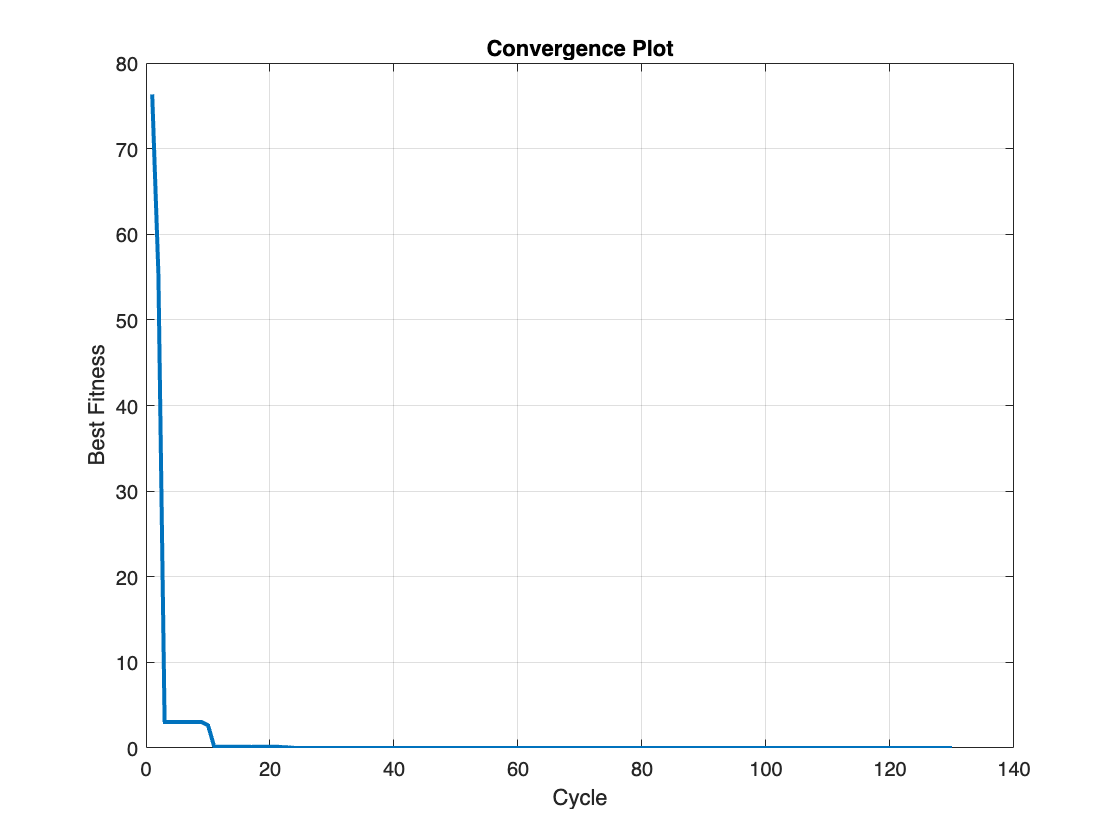

plot(1:length(best_fitness_history), best_fitness_history, 'LineWidth', 2);
title('Convergence Plot');
xlabel('Cycle');
ylabel('Best Fitness');
grid on;

## Section 6: Visualize the output.

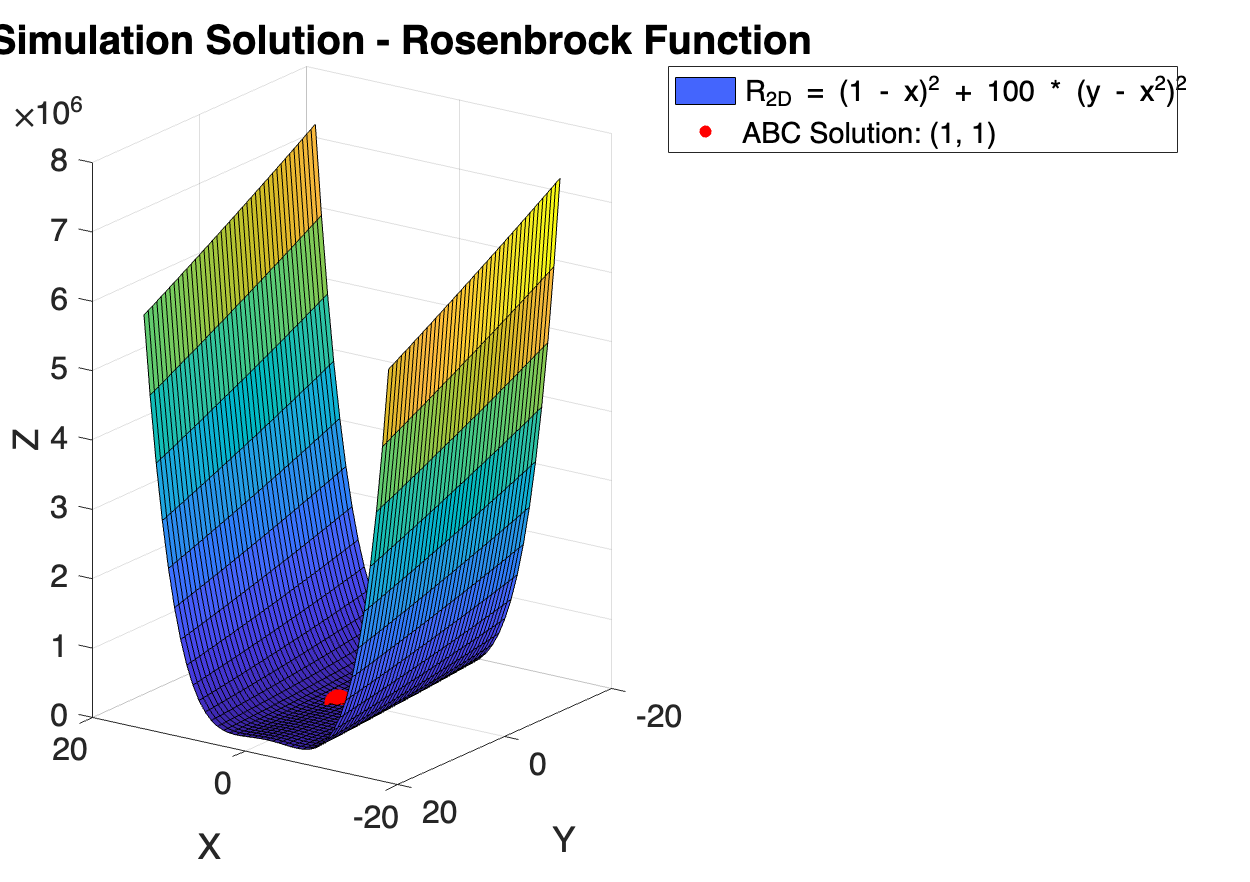

close all; figure('Position', [100, 100, 850, 600]);

x_range = lower_bound(1):.8:upper_bound(1);
y_range = lower_bound(2):.8:upper_bound(2);
[X, Y] = meshgrid(x_range, y_range);
rosenbrock_values = rosenbrock(X, Y);
surf(X, Y, rosenbrock_values, 'DisplayName', ...
    sprintf('R_{2D} = (%d - x)^2 + %d * (y - x^2)^2', a, b)); hold on;
scatter3(best_solution(1), best_solution(2), best_fitness, 200, 'r', ...
    'filled','DisplayName', ['ABC Solution: (', num2str(best_solution(1)), ...
    ', ', num2str(best_solution(2)), ')']); hold off;

azimuth = -145; 
elevation = 12; 
view(azimuth, elevation);
ax = gca; ax.FontSize = 16;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('ABC Simulation Solution - Rosenbrock Function', 'FontSize', 20);
legend('show');

The plot should show above. Click the arrow in the upper right to open a separate MATLAB figure with this graph to rotate it in 3D!

# Let's now optimize the Ackley function! 

[Ackley function](https://www.sfu.ca/~ssurjano/ackley.html#:~:text=The%20Ackley%20function%20is%20widely,large%20hole%20at%20the%20centre.):   $\[ f(x, y) = -20 \exp\left(-0.2 \sqrt{0.5(x^2 + y^2)}\right) - \exp\left(0.5(\cos(2\pi x) + \cos(2\pi y))\right) + e + 20 \]
$

Analytic solution: $\[ f(0, 0) = 0 \]$

Domain:               $\[ -5 \leq x, y \leq 5 \]$

## Section 1: Set up the function

Function:

Code:

actual_solution = [0, 0];
ackley = @(x, y) AckleyFunction(x, y);

## Section 2: Parameters

SN = 50;        % Size of the population (# of employed and onlooker bees)  % Original: 50
D = 2;          % Number of optimization parameters (System Dimension)      % Original: 2
MCN = 500;      % Maximum Cycle Number (Maximum number of loop iterations)  % Original: 500
limit = 20;     % Number of cycles for food source to be abandoned          % Original: 20

## Section 3: Initialization

Functions:

Code:

lower_bound = [-5, -5]; % [x_lower, y_lower]                             % Original: [-16, -16]
upper_bound = [5, 5];   % [x_upper, y_upper]                             % Original: [16, 16]
employed_positions = generateFoodSources(SN,lower_bound, upper_bound); 
onlooker_positions = NaN(SN, D);
onlooker_fitness = NaN(SN, D);
count_arr = zeros(SN, 1);
employed_fitness = AckleyFunction(employed_positions(:, 1), employed_positions(:, 2));

## Section 4: Optimization Loop

Functions:

Code:

for cycle = 1:MCN
    % First, the employed bees explore solutions. 
    [employed_positions, count_arr] = employedBeeRoutine_1(employed_positions, ... 
        count_arr, employed_fitness, ackley, D, lower_bound, upper_bound);
    employed_fitness = AckleyFunction(employed_positions(:, 1), employed_positions(:, 2));
    
    % Then, onlooker bees go to the best solutions.
    onlooker_positions = onlookerBeeRoutine_1(onlooker_positions, onlooker_fitness, ...
        employed_positions, employed_fitness, ackley, D, lower_bound, upper_bound);
    onlooker_fitness = AckleyFunction(onlooker_positions(:, 1), onlooker_positions(:, 2));
    
    % Finally, we check that no food sources have been exhausted.
    employed_positions = scoutBeeRoutine_1(employed_positions, count_arr, ... 
        lower_bound, upper_bound, limit);  
    employed_fitness = AckleyFunction(employed_positions(:, 1), employed_positions(:, 2));
    
    % Store the best fitness value at each cycle
    best_fitness_history(cycle) = min(employed_fitness);

    % User Updates!
    if mod(cycle, 5) == 0
        fprintf('Finished with cycle: %d. Best Fitness of Cycle = %f. \n', ...
            cycle, min(employed_fitness));
    end
    if min(employed_fitness) < 1e-14
        fprintf('\nGlobal Minimum Located. Exiting Loop. \n');
        break;
    end
end

   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 5. Best Fitness of Cycle = 0.509697. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 10. Best Fitness of Cycle = 0.346541. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 15. Best Fitness of Cycle = 0.113650. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 20. Best Fitness of Cycle = 0.051401. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 25. Best Fitness of Cycle = 0.004720. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 30. Best Fitness of Cycle = 0.002722. 


   0 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 35. Best Fitness of Cycle = 0.001930. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 40. Best Fitness of Cycle = 0.000159. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 45. Best Fitness of Cycle = 0.000159. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 50. Best Fitness of Cycle = 0.000111. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 55. Best Fitness of Cycle = 0.000029. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 60. Best Fitness of Cycle = 0.000009. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 65. Best Fitness of Cycle = 0.000005. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 70. Best Fitness of Cycle = 0.000002. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 75. Best Fitness of Cycle = 0.000001. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 80. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 85. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 90. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 95. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 100. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 105. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 110. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 115. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 120. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 125. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 130. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 135. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 140. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 145. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 150. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 155. Best Fitness of Cycle = 0.000000. 


   0 abandoned food sources. 
   0 abandoned food sources. 



Global Minimum Located. Exiting Loop. 


## Section 5: Final Results

fprintf('\nCycles Performed: %d. \n', cycle);


Cycles Performed: 157. 


[best_fitness, index] = min(employed_fitness);
best_solution = employed_positions(index, :);
fprintf('The Best Solution Is: (%f, %f). Its Fitness Is: %.2f. \n', ...
    best_solution(1), best_solution(2), best_fitness);

The Best Solution Is: (0.000000, 0.000000). Its Fitness Is: 0.00. 


fprintf('Distance from the analytic solution: %f. \n', ...
    sqrt(sum((best_solution - actual_solution).^2)))

Distance from the analytic solution: 0.000000. 


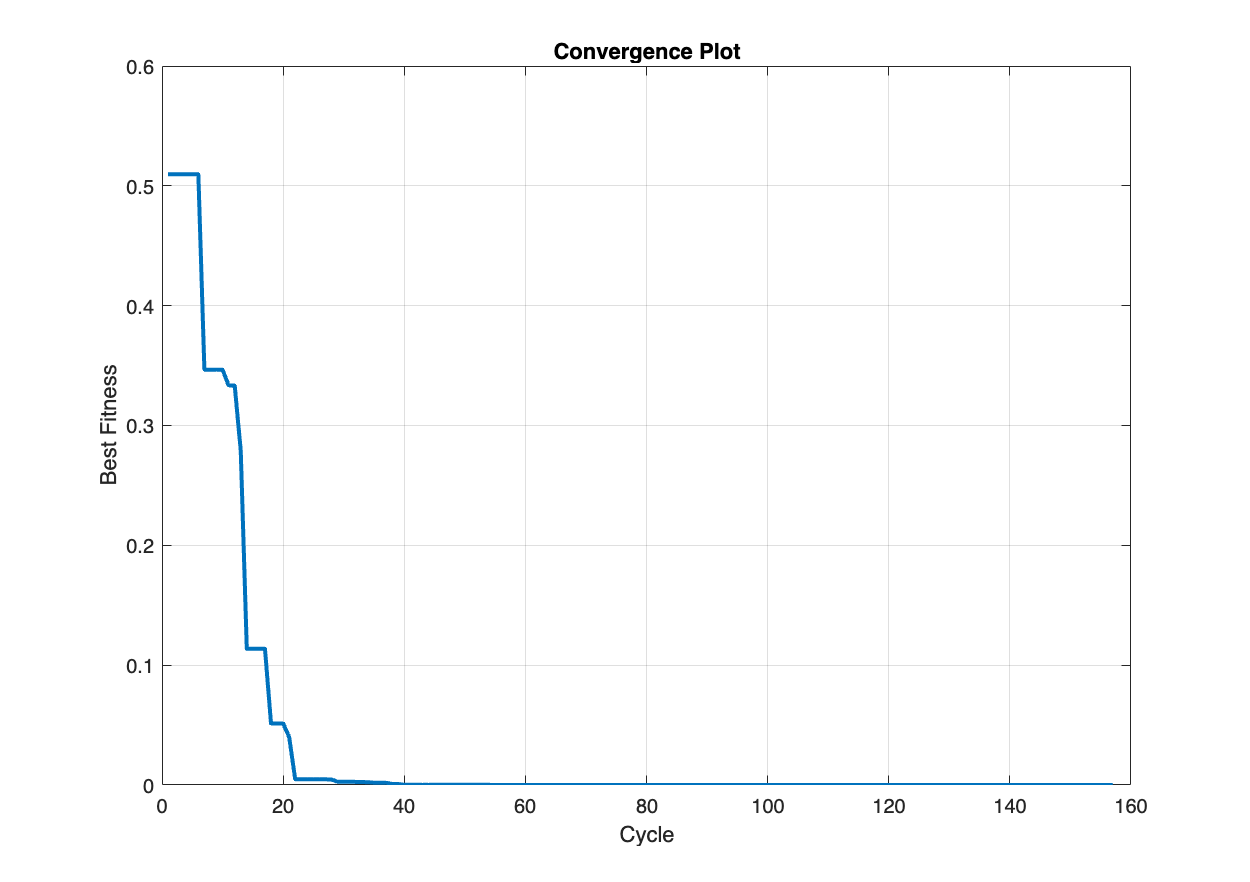

plot(1:length(best_fitness_history), best_fitness_history, 'LineWidth', 2);
title('Convergence Plot');
xlabel('Cycle');
ylabel('Best Fitness');
grid on;

## Section 6: Visualize Results

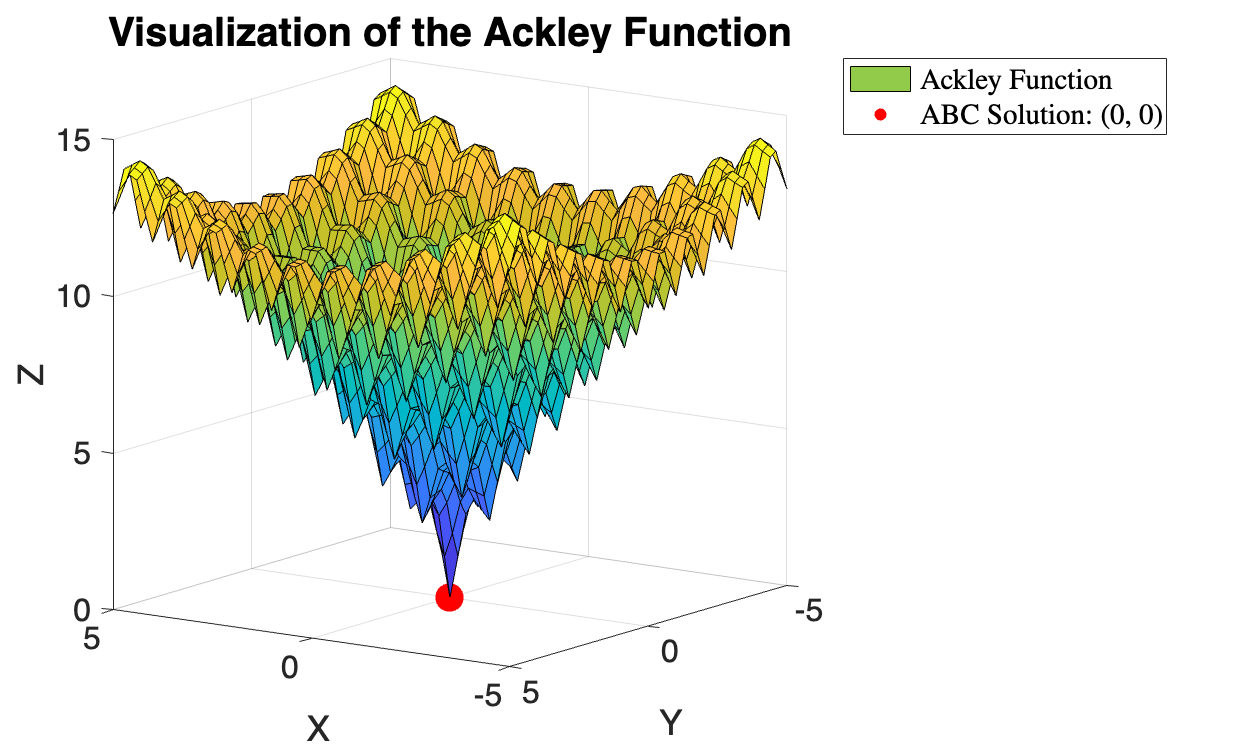

% Define the range for x and y
x_range = -5:0.2:5;
y_range = -5:0.2:5;

% Create a meshgrid for x and y
[X, Y] = meshgrid(x_range, y_range);

% Evaluate myFunction for each point in the meshgrid
myFunction_values = AckleyFunction(X, Y);

% Plot the 3D surface
figure('Position', [100, 100, 1000, 600]);
surf(X, Y, myFunction_values);
hold on;

% Scatter plot for the solution at (0, 0)
scatter3(0, 0, AckleyFunction(0, 0), 200, 'r', 'filled');

hold off;

% Set plot properties
azimuth = -145;
elevation = 12;
view(azimuth, elevation);
ax = gca;
ax.FontSize = 16;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Visualization of the Ackley Function', 'FontSize', 20);
legend('Ackley Function', sprintf('ABC Solution: (%.0f, %.0f)', best_solution(1), best_solution(2)), ...
    'Interpreter', 'Latex');

The plot should show above. Click the arrow in the upper right to open a separate MATLAB figure with this graph to rotate it in 3D!

# Example 2: Minimizing a function with Constraints

This script walks through using the ABC algorithm for constrained, single single objective optimization using the Gomez and Levy function.

Gomez and Levy function:   $\[
f(x, y) = 4x^2 - 2.1x^4 + \frac{1}{3}x^6 + xy - 4y^2 + 4y^4
\]$

with constraint:                    $\[
-\sin(4\pi x) + 2\sin^2(2\pi y) \leq 1.5
\]$

This function has solution:   $\[
f(0.08984201, -0.7126564) = -1.031628453
\]$

Its search domain is:           $\[
-1 \leq x \leq 0.75, \quad -1 \leq y \leq 1
\]$

See: [This paper, Problem 30 (page 394)](https://www.researchgate.net/publication/344048036_A_collection_of_bivariate_nonlinear_optimisation_test_problems_with_graphical_representations).

All functions are defined at the end of the script.

## Section 1: Defining the function and its constraints

Gomez and Levy function

This follows a similar implementation to Stage 1. However, note the new 'constraint_function'!

Functions:

Code:

clc; clearvars;

actual_solution = [0.08984201, -0.7126564];
min_value = -1.031628453;
GomezLevy = @(x, y) GomezLevy_function(x, y);

## Section 2: Parameters

The setup here is the exact same as Example 1. Run with these parameters, and then see what happens when you change them! The original values are included to the right of the variables. Remember:

A general rule of thumb - the greater your population size 'SN', the more difficult it is to converge to a solution (i.e., 'MCN' and 'limit' must be larger too). A good starting point is setting SN = 20, and MCN to a few hundred, and going from there. Note: 20 < SN < 500 and limit = ~ 0.1*MCN is a good rule of thumb for most problems!  

If your problem doesn't converge with the parameters you set, adjust them! If you aren't getting expected fitness values at the end of your iteration limit, try increasing MCN (& limit)! If this still doesn't work, try increasing SN! Repeat until you find the parameters that reliably give a solution.

SN = 50;         % Size of the population                                   % Original: 50
D = 2;           % Number of optimization parameters                        % Original: 2
MCN = 150;       % Maximum Cycle Number                                     % Original: 250
limit = 50;     % Number of cycles for food source to be abandoned          % Original: 50

## Section 3: Initialization

This section initializes the solution arrays of the system! Same setup as Example 1.

Note: Nothing needs to be changed here! The search space is already defined for the Gomez and Levy function.

Functions:

Code:

lower_bound = [-1, -1];  % [x_lower, y_lower]               
upper_bound = [0.75, 1]; % [x_upper, y_upper]  
employed_positions = generateFoodSources(SN, lower_bound, upper_bound); 
onlooker_positions = NaN(SN, D);
onlooker_fitness = NaN(SN, 1);
count_arr = zeros(SN, 1);

evaluateFitnessGL_handle = @(population) evaluateFitnessGL(population);
employed_fitness = evaluateFitnessGL_handle(employed_positions);

## Section 4: Optimization Loop

This loop carries out the ABC algorithm! Again, same setup as Stage 1.

Functions:

Code:

for cycle = 1:MCN
    % First, the employed bees explore solutions.
    [employed_positions, count_arr] = employedBeeRoutine_vectorized(employed_positions, ...
        count_arr, employed_fitness, evaluateFitnessGL_handle, D, lower_bound, upper_bound);
    employed_fitness = evaluateFitnessGL(employed_positions);

    % Then, onlooker bees go to the best solutions.
    onlooker_positions = onlookerBeeRoutine_vectorized( ...
        onlooker_positions, onlooker_fitness, employed_positions, employed_fitness, evaluateFitnessGL_handle, D, lower_bound, upper_bound);
    onlooker_fitness = evaluateFitnessGL(onlooker_positions);

    % Finally, we check that no food sources have been exhausted.
    employed_positions = scoutBeeRoutine_1(employed_positions, count_arr, ...
        lower_bound, upper_bound, limit);
    employed_fitness = evaluateFitnessGL(employed_positions);
    
    % Store the best fitness value at each cycle
    best_fitness_history(cycle) = min(employed_fitness);

    % User updates!
    if mod(cycle, 5) == 0
        fprintf('Finished with cycle: %d. Best Fitness of Cycle = %f. \n', cycle, ...
            min(employed_fitness));
    end

    % if min(employed_fitness) - min_value < 1e-24
    %     fprintf('\nGlobal Minimum Located. Exiting Loop. \n');
    %     break;
    % end
end

   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 5. Best Fitness of Cycle = -0.981446. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 10. Best Fitness of Cycle = -1.028400. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 15. Best Fitness of Cycle = -1.028728. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 20. Best Fitness of Cycle = -1.029376. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 25. Best Fitness of Cycle = -1.031051. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 30. Best Fitness of Cycle = -1.031275. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 35. Best Fitness of Cycle = -1.031571. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 40. Best Fitness of Cycle = -1.031625. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 45. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 50. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 55. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 60. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 65. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 70. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 75. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 80. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 85. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 90. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 95. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 100. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 105. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 110. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 115. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 120. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 125. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 130. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 135. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 140. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 145. Best Fitness of Cycle = -1.031628. 


   0 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 150. Best Fitness of Cycle = -1.031628. 


## Section 5: Final Results

fprintf('\nCycles Performed: %d. \n', cycle);


Cycles Performed: 150. 


[best_fitness, index] = min(employed_fitness);
best_solution = employed_positions(index, :);
fprintf('The Best Solution Is: (%f, %f). Its Fitness Is: %.4f. \n', ...
    best_solution(1), best_solution(2), best_fitness);

The Best Solution Is: (0.089842, -0.712656). Its Fitness Is: -1.0316. 


fprintf('Distance from the analytic solution: %f. \n', ... 
     sqrt(sum((best_solution - actual_solution).^2)));

Distance from the analytic solution: 0.000000. 


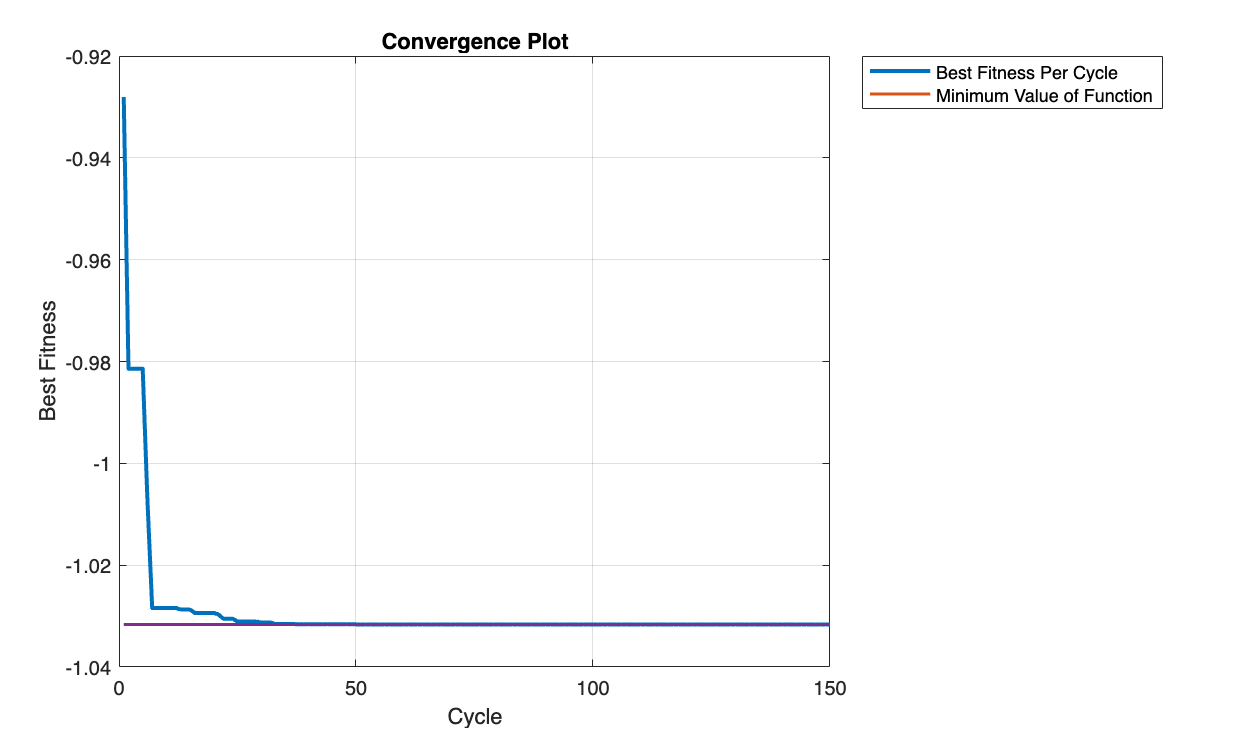

plot(1:length(best_fitness_history), best_fitness_history, 'LineWidth', 2); hold on;
plot(1:length(best_fitness_history), min_value*ones(length(best_fitness_history)), 'Linewidth', 1.5); hold off;
title('Convergence Plot');
xlabel('Cycle');
ylabel('Best Fitness');
legend('Best Fitness Per Cycle', 'Minimum Value of Function')
grid on;

## Section 6: Graph

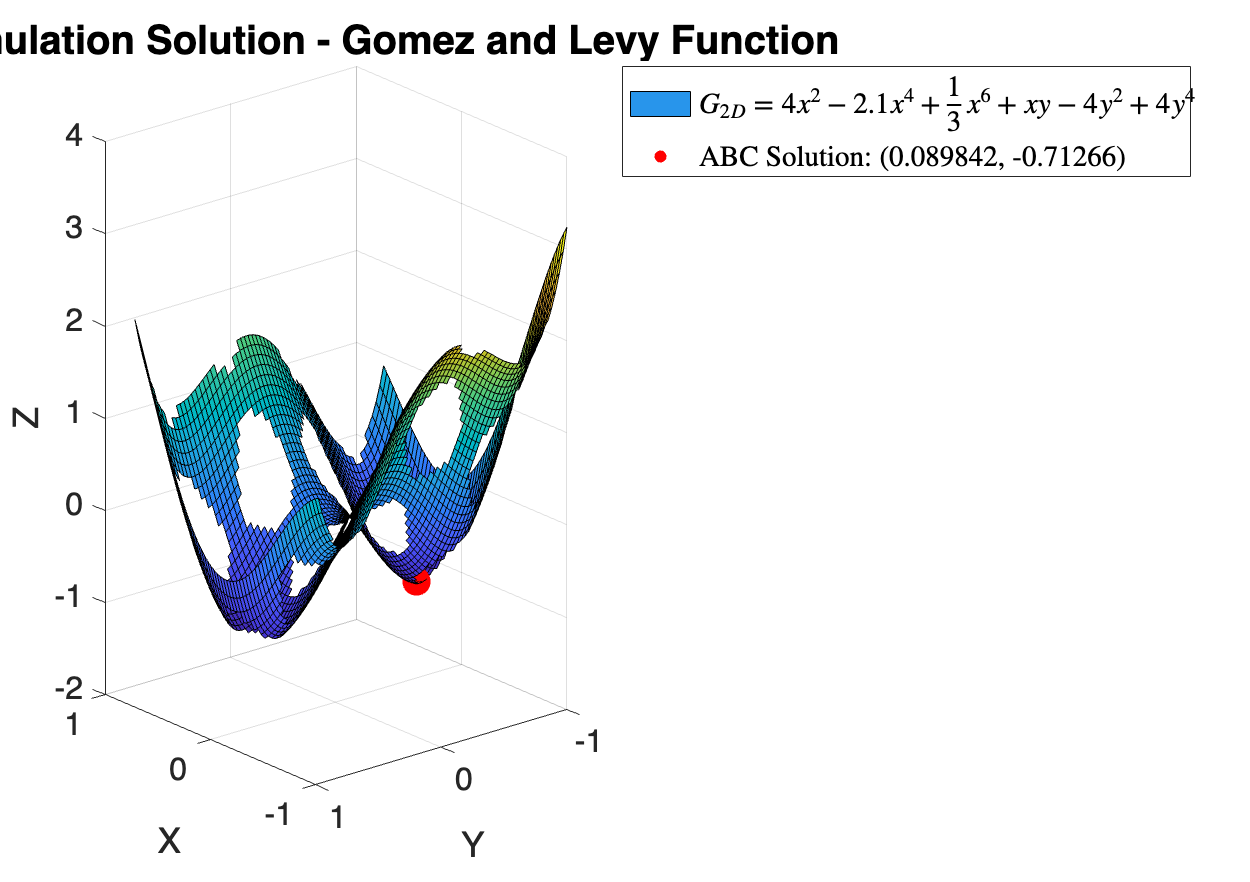

close all; figure('Position', [100, 100, 850, 600]);
[X, Y] = meshgrid(lower_bound(1):.03:upper_bound(1), lower_bound(2):0.03:upper_bound(2));
GomezLevy_values = GomezLevy(X, Y);
constraints = constraint_function(X, Y);
GomezLevy_values(constraints > 0) = NaN;
surf(X, Y, GomezLevy_values, 'DisplayName', ... 
    '$G_{2D} = 4x^{2} - 2.1x^{4} + \frac{1}{3}x^{6} + xy - 4y^{2} + 4y^{4}$'); hold on;
scatter3(best_solution(1), best_solution(2), best_fitness, 200, 'r', 'filled'); hold off;

azimuth = -130; 
elevation = 12; 
view(azimuth, elevation);
ax = gca; ax.FontSize = 16;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('ABC Simulation Solution - Gomez and Levy Function', 'FontSize', 20);
legend('$G_{2D} = 4x^{2} - 2.1x^{4} + \frac{1}{3}x^{6} + xy - 4y^{2} + 4y^{4}$', ...
    ['ABC Solution: (', num2str(best_solution(1)), ', ', num2str(best_solution(2)), ')'], ...
    'Interpreter', 'Latex');

The plot should show above. Click the arrow in the upper right to open a separate MATLAB figure with this graph to rotate it in 3D!

# Let's optimize Mishra's Bird Function

The Mishra's Bird function (modified) is defined as follows:


$$\[
f(x, y) = \sin(y) \cdot \exp\left((1 - \cos(x))^2\right) + \cos(x) \cdot \exp\left((1 - \sin(y))^2\right) + (x - y)^2
\]$$


subject to the constraint:


$$\[
(x + 5)^2 + (y + 5)^2 < 25
\]$$


The analytic solution for this function is:


$$\(f(-3.1302468, -1.5821422) = -106.7645367\)$$


In addition, the variables are constrained as follows: 


$$\(-10 \leq x \leq 0\) and \(-6.5 \leq y \leq 0\)$$


See: 

## Section 1: Defining the function

Function:

Code:

clc; clearvars;

actual_solution = [-3.1302568, -1.5821422];
min_value = -106.7645367;
mishra = @(x, y) MishraBF(x, y);

## Section 2: Parameters

SN = 100;         % Size of the population                                   % Original: 50
D = 2;            % Number of optimization parameters                        % Original: 2
MCN = 250;        % Maximum Cycle Number                                     % Original: 250
limit = 40;       % Number of cycles for food source to be abandoned         % Original: 50

## Section 3: Initialization

Functions:

Code:

lower_bound = [-10, -6.5];  % [x_lower, y_lower]               
upper_bound = [0, 0];       % [x_upper, y_upper]  
employed_positions = generateFoodSources(SN, lower_bound, upper_bound); 
onlooker_positions = NaN(SN, D);
onlooker_fitness = NaN(SN, 1);
count_arr = zeros(SN, 1);

evaluateFitnessMBF_handle = @(population) evaluateFitnessMBF(population);
employed_fitness = evaluateFitnessMBF_handle(employed_positions);

## Section 4: Optimization Loop

Functions:

Code:

for cycle = 1:MCN
    % First, the employed bees explore solutions.
    [employed_positions, count_arr] = employedBeeRoutine_vectorized(employed_positions, ...
        count_arr, employed_fitness, evaluateFitnessMBF_handle, D, lower_bound, upper_bound);
    employed_fitness = evaluateFitnessMBF(employed_positions);

    % Then, onlooker bees go to the best solutions.
    onlooker_positions = onlookerBeeRoutine_vectorized( ...
        onlooker_positions, onlooker_fitness, employed_positions, employed_fitness, evaluateFitnessMBF_handle, D, lower_bound, upper_bound);
    onlooker_fitness = evaluateFitnessMBF(onlooker_positions);

    % Finally, we check that no food sources have been exhausted.
    employed_positions = scoutBeeRoutine_1(employed_positions, count_arr, ...
        lower_bound, upper_bound, limit);
    employed_fitness = evaluateFitnessMBF(employed_positions);
    
    % Store the best fitness value at each cycle
    best_fitness_history(cycle) = min(employed_fitness);

    % User updates!
    if mod(cycle, 5) == 0
        fprintf('Finished with cycle: %d. Best Fitness of Cycle = %f. \n', cycle, ...
            min(employed_fitness));
    end
end

   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 5. Best Fitness of Cycle = -102.119829. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 10. Best Fitness of Cycle = -106.694662. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 15. Best Fitness of Cycle = -106.694662. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 20. Best Fitness of Cycle = -106.694662. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 25. Best Fitness of Cycle = -106.754112. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 30. Best Fitness of Cycle = -106.758724. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 35. Best Fitness of Cycle = -106.764159. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 40. Best Fitness of Cycle = -106.764499. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 45. Best Fitness of Cycle = -106.764532. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 50. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 55. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 60. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 65. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 70. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 75. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 80. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 85. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 90. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 95. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 100. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 105. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 110. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 115. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 120. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 125. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 130. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 135. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 140. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 145. Best Fitness of Cycle = -106.764537. 


   1 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   2 abandoned food sources. 


Finished with cycle: 150. Best Fitness of Cycle = -106.764537. 


   1 abandoned food sources. 
   1 abandoned food sources. 
   2 abandoned food sources. 
   3 abandoned food sources. 
   3 abandoned food sources. 


Finished with cycle: 155. Best Fitness of Cycle = -106.764537. 


   6 abandoned food sources. 
   7 abandoned food sources. 
   8 abandoned food sources. 
   3 abandoned food sources. 
   2 abandoned food sources. 


Finished with cycle: 160. Best Fitness of Cycle = -106.764537. 


   4 abandoned food sources. 
   2 abandoned food sources. 
   4 abandoned food sources. 
   5 abandoned food sources. 
   3 abandoned food sources. 


Finished with cycle: 165. Best Fitness of Cycle = -106.764537. 


   6 abandoned food sources. 
   5 abandoned food sources. 
   5 abandoned food sources. 
   4 abandoned food sources. 
   6 abandoned food sources. 


Finished with cycle: 170. Best Fitness of Cycle = -106.764537. 


   4 abandoned food sources. 
   8 abandoned food sources. 
   3 abandoned food sources. 
   3 abandoned food sources. 
   4 abandoned food sources. 


Finished with cycle: 175. Best Fitness of Cycle = -106.764537. 


   4 abandoned food sources. 
   2 abandoned food sources. 
   4 abandoned food sources. 
   4 abandoned food sources. 
   5 abandoned food sources. 


Finished with cycle: 180. Best Fitness of Cycle = -106.764537. 


   2 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   2 abandoned food sources. 
   3 abandoned food sources. 


Finished with cycle: 185. Best Fitness of Cycle = -106.764537. 


   1 abandoned food sources. 
   3 abandoned food sources. 
   3 abandoned food sources. 
   2 abandoned food sources. 
   2 abandoned food sources. 


Finished with cycle: 190. Best Fitness of Cycle = -106.764537. 


   3 abandoned food sources. 
   3 abandoned food sources. 
   3 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 195. Best Fitness of Cycle = -106.764537. 


   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 200. Best Fitness of Cycle = -106.764537. 


   2 abandoned food sources. 
   3 abandoned food sources. 
   2 abandoned food sources. 
   2 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 205. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 210. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 215. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 
   1 abandoned food sources. 


Finished with cycle: 220. Best Fitness of Cycle = -106.764537. 


   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 225. Best Fitness of Cycle = -106.764537. 


   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 230. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 235. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   1 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 240. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 245. Best Fitness of Cycle = -106.764537. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 250. Best Fitness of Cycle = -106.764537. 


## Section 5: Final Results

fprintf('\nCycles Performed: %d. \n', cycle);


Cycles Performed: 250. 


[best_fitness, index] = min(employed_fitness);
best_solution = employed_positions(index, :);
fprintf('The Best Solution Is: (%f, %f). Its Fitness Is: %.4f. \n', ...
    best_solution(1), best_solution(2), best_fitness);

The Best Solution Is: (-3.130247, -1.582142). Its Fitness Is: -106.7645. 


fprintf('Distance from the analytic solution: %f. \n', ... 
     sqrt(sum((best_solution - actual_solution).^2)));

Distance from the analytic solution: 0.000010. 


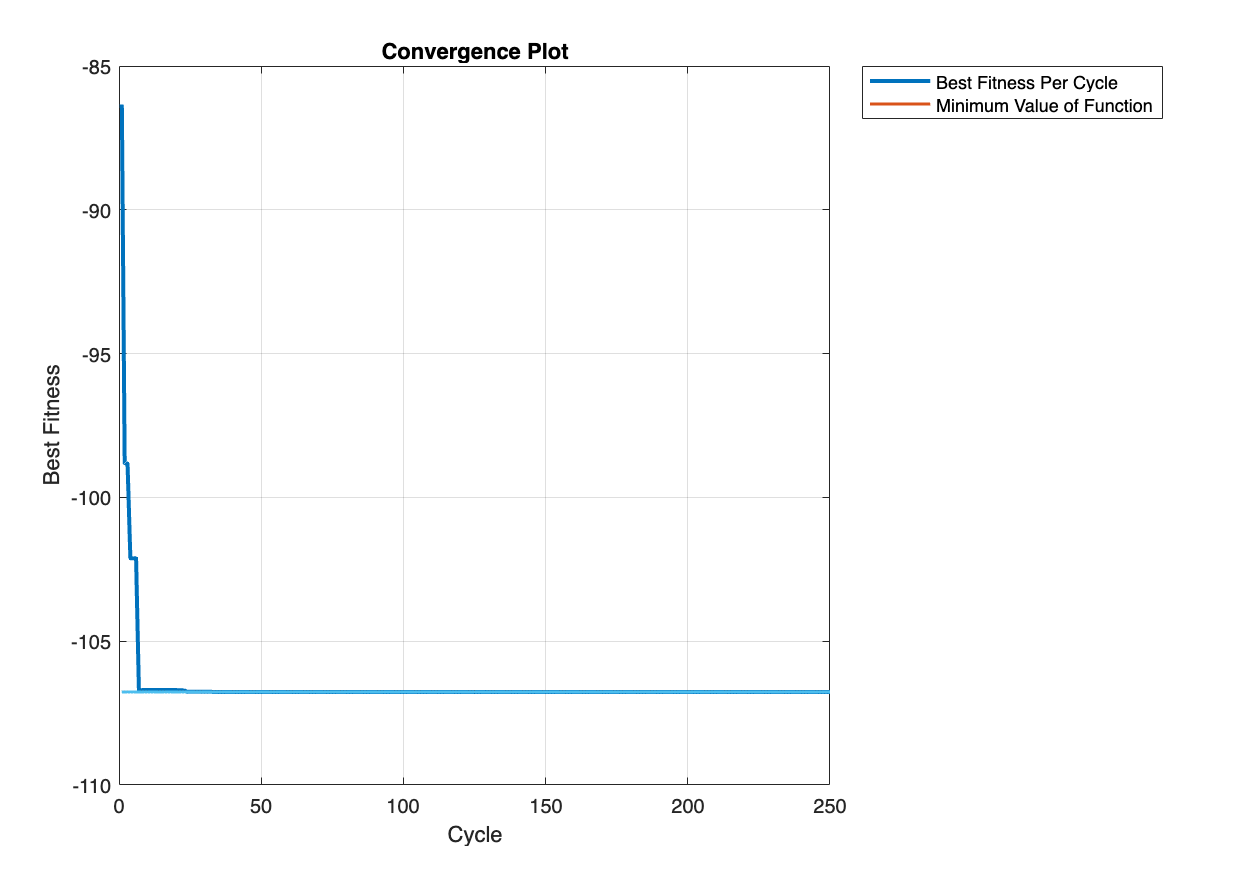

plot(1:length(best_fitness_history), best_fitness_history, 'LineWidth', 2); hold on;
plot(1:length(best_fitness_history), min_value*ones(length(best_fitness_history)), 'Linewidth', 1.5); hold off;
title('Convergence Plot');
xlabel('Cycle');
ylabel('Best Fitness');
legend('Best Fitness Per Cycle', 'Minimum Value of Function')
grid on;

## Section 6: Visualize the output

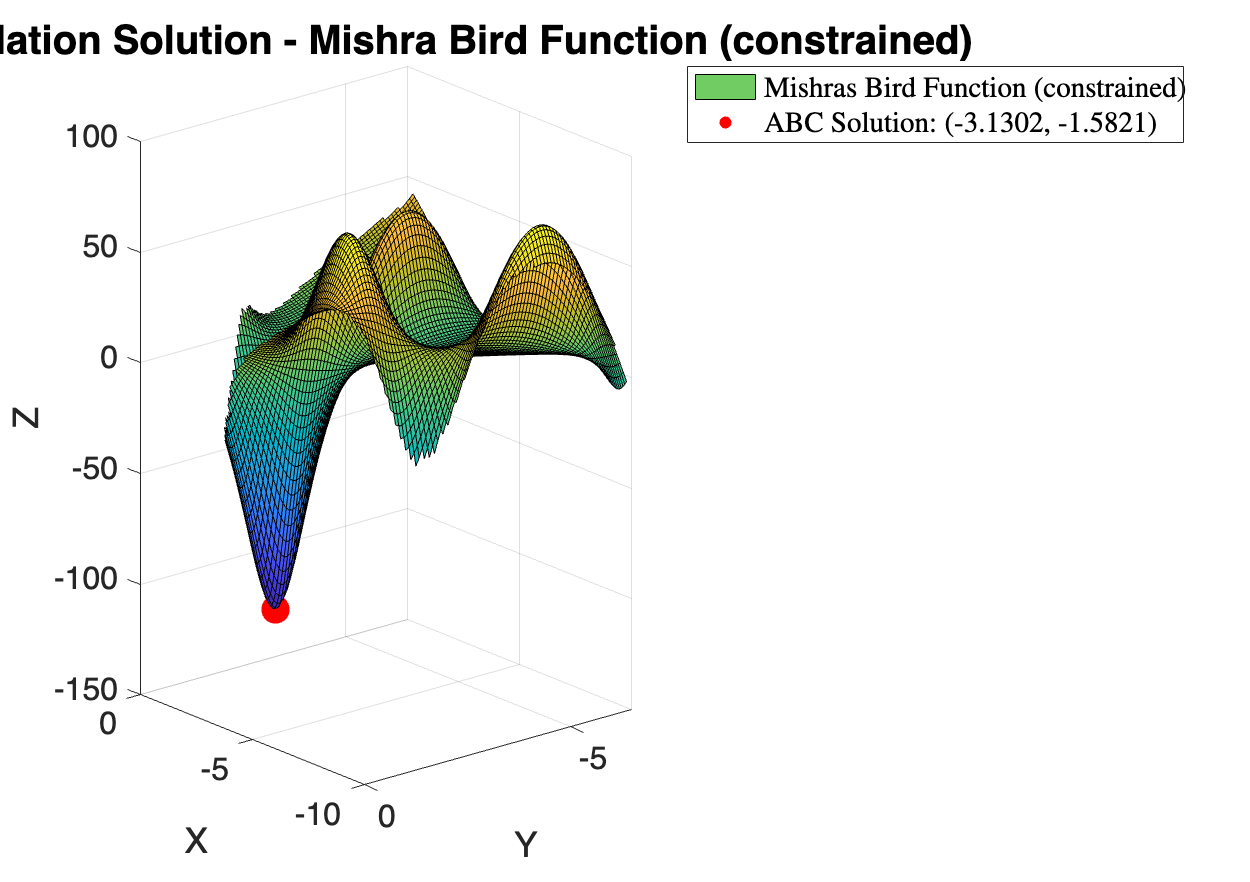

% Evaluate the objective function and apply penalty for constraints
x_range = lower_bound(1):0.08:upper_bound(1);
y_range = lower_bound(2):0.08:upper_bound(2);
[X, Y] = meshgrid(x_range, y_range);

% Evaluate fitness values using evaluateFitnessGL_handle
MishraValues = MishraBF(X, Y);

% Apply constraints
constraints = constraint_function_MBF(X, Y);
MishraValues(constraints > 0) = NaN;

% Plot the surface
figure('Position', [100, 100, 850, 600]);
surf(X, Y, MishraValues); 
hold on;

% Add scatter plot for the best solution
best_fitness = evaluateFitnessMBF_handle(best_solution);
scatter3(best_solution(1), best_solution(2), best_fitness, 200, 'r', 'filled');

hold off;

% Set plot properties
azimuth = -130; 
elevation = 12; 
view(azimuth, elevation);
ax = gca; ax.FontSize = 16;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('ABC Simulation Solution - Mishra Bird Function (constrained)', 'FontSize', 20);
legend('Mishras Bird Function (constrained)', ...
    ['ABC Solution: (', num2str(best_solution(1)), ', ', num2str(best_solution(2)), ')'], ...
    'Interpreter', 'Latex');

The plot should show above. Click the arrow in the upper right to open a separate MATLAB figure with this graph to rotate it in 3D!

# Example 3: Portfolio Optimization

This script walks through using the ABC algorithm for optimizing real-world stock data with the Sharpe ratio! It will give you the optimal weights (a set of normalized values between zero and one, with a weight for each company being considered) to maximize profit while also considering risk.

The Sharpe ratio measures the risk-adjusted performance of an investment or portfolio. It is defined as the ratio of the excess return (the return above the risk-free rate) by a measure of its volatility (here we use standard deviation) to evaluate the risk-adjusted performance of our portfolio. See: [Sharpe Ratio Explanation](https://www.investopedia.com/terms/s/sharperatio.asp).

The formula for the Sharpe ratio used here is: 


$$\[
S = \frac{\text{Mean\_return}}{\text{std(Returns)}}
\]$$


 I have added a penalty term to give the user the option to encourage portfolio diversity. The updated formula is given by:


$$\[
S_{\text{penalty}} = \frac{S}{\sqrt{1 + \text{penalty\_factor}}}
\]$$


See the 'Function Definitions’' section for more details.

All functions are defined at the end of the script.

## Section 1: Load and Process Stock Data

I got my data from here: [Nasdaq Stock Information](https://www.nasdaq.com/market-activity/quotes/historical). I chose the '1 year' option for my downloads. Feel free to evaluate the data of other companies! Ignore the warning displayed.

clc; clearvars;

% Load stock data for multiple companies
Apple = readtable('Apple1year.csv');

Starbucks = readtable('Starbucks1year.csv');

Amazon = readtable('Amazon1year.csv');


stockData = {Apple, Starbucks, Amazon}; % cell array containing data for each company
name_arr = ["Apple", "Starbucks", "Amazon"];

% Convert data to an acceptable format
for i = 1:numel(stockData)
    % Remove '$' sign and apostrophes, and convert 'Close_Last' column to numeric values
    stockData{i}.Close = str2double(strrep(strrep(stockData{i}.Close_Last, '$', ''), '''', ''));
end

% Combine the closing prices for the companies into a single matrix
closingPrices = cell2mat(cellfun(@(data) data.Close, stockData, 'UniformOutput', false));

## Section 2: Define the Portfolio Optimization Function using the Sharpe Ratio

This section contains two user-adjustable parameters, '**max_weight'** and **'penalty_factor'**. Start with max_weight = 0, so there is no penalty for stock prices going above a certain value. Note that your portfolio favors the most conservative stock option! Re-run with a new max_weight value. For a portfolio of three companies, I recommend setting max_weight = 0.45. This will penalize any weight that goes above this value!

'penalty_factor' controls the strength of our penalty condition. Higher values penalize our function more. I recommend a value between 15 and 20, but feel free to experiment!

Functions: 

Code:

max_weight = 0;      % Maximum allowed weight for any individual asset
penalty_factor = 18; % Factor controlling the strength of the penalty
SharpeRatio = @(x) SharpeRatio_function(x, closingPrices, max_weight, penalty_factor);

## Section 3: Parameters

The setup here is the exact same as examples 1 and 2. 

Remember: A good starting point is setting SN = 20, and MCN to a few hundred, and going from there. Note: 20 < SN < 500 and limit = ~ 0.1*MCN is a good rule of thumb for most problems!  

If your problem doesn't converge with the parameters you set, adjust them! If you aren't getting expected fitness values at the end of your iteration limit, try increasing MCN (& limit)! If this still doesn't work, try increasing SN! Repeat until you find the parameters that reliably return a solution.

SN = 20;                    % Size of the population
D = size(stockData, 2);     % Number of optimization parameters (equal to the size of your portfolio)
MCN = 100;                  % Maximum Cycle Number
limit = 100;                % Number of cycles for food source to be abandoned

## Section 4: Initialization 

This section initializes the solution arrays of the system! Same setup as stages 1 and 2.

Note: Nothing needs to be changed here! Portfolio weights must be between 0 and 1, so our upper and lower bounds are already defined!

Functions:

Code:

lower_bound = zeros(1, D);  % [x_lower, y_lower]           
upper_bound = ones(1, D);   % [x_upper, y_upper]  
employed_positions = generateFoodSourcesStocks(SN, lower_bound, upper_bound); 
onlooker_positions = NaN(SN, D);
onlooker_fitness = NaN(SN, D);
count_arr = zeros(SN, 1);
employed_fitness = evaluateFitnessStocks(employed_positions, closingPrices, ...
    max_weight, penalty_factor); % Note that we need more parameters here!


## Section 5: Optimization loop

This loop carries out the ABC algorithm!

Functions:

Code:

for cycle = 1:MCN
    % First, the employed bees explore solutions.
    [employed_positions, count_arr] = employedBeeRoutine_vectorized_Stocks(employed_positions, ...
        count_arr, employed_fitness, closingPrices, D, lower_bound, ...
        upper_bound, max_weight, penalty_factor);
    employed_fitness = evaluateFitnessStocks(employed_positions, closingPrices,... 
        max_weight, penalty_factor);

    % Then, onlooker bees go to the best solutions.
    onlooker_positions = onlookerBeeRoutine_vectorized_Stocks(onlooker_positions,... 
        onlooker_fitness, employed_positions, employed_fitness,...
        closingPrices, D, lower_bound, upper_bound, max_weight, penalty_factor);
    onlooker_fitness = evaluateFitnessStocks(onlooker_positions, closingPrices,...
        max_weight, penalty_factor);

    % Store the best fitness value at each cycle
    best_fitness_history(cycle) = min(employed_fitness);

    % Finally, we check that no food sources have been exhausted.
    employed_positions = scoutBeeRoutine_Stocks(employed_positions, count_arr,...
        lower_bound, upper_bound, limit);
    employed_fitness = evaluateFitnessStocks(employed_positions, closingPrices,...
        max_weight, penalty_factor);
    if mod(cycle, 5) == 0
        fprintf('Finished with cycle: %d. Best Fitness of Cycle = %f. \n', cycle, min(employed_fitness));
    end
end

   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 5. Best Fitness of Cycle = -6.672932. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 10. Best Fitness of Cycle = -7.019077. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 15. Best Fitness of Cycle = -7.019077. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 20. Best Fitness of Cycle = -7.048826. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 25. Best Fitness of Cycle = -7.062825. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 30. Best Fitness of Cycle = -7.065361. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 35. Best Fitness of Cycle = -7.065361. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 40. Best Fitness of Cycle = -7.065551. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 45. Best Fitness of Cycle = -7.065570. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 50. Best Fitness of Cycle = -7.065575. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 55. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 60. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 65. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 70. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 75. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 80. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 85. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 90. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 95. Best Fitness of Cycle = -7.065576. 


   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 
   0 abandoned food sources. 


Finished with cycle: 100. Best Fitness of Cycle = -7.065576. 


## Section 6: Final Results

fprintf('\nCycles Performed: %d. \n', cycle);


Cycles Performed: 100. 


[best_fitness, index] = min(employed_fitness);
best_solution = employed_positions(index, :);
fprintf('The best weights are: [%.3f, %.3f, %.3f]. \n', best_solution(1), ...
    best_solution(2), best_solution(3));

The best weights are: [0.090, 0.805, 0.105]. 


fprintf('The sum of these weights is: %.1f. \nIt should be 1!', sum(best_solution))

The sum of these weights is: 1.0. 
It should be 1!

## Section 7: Visualize the optimized portfolio

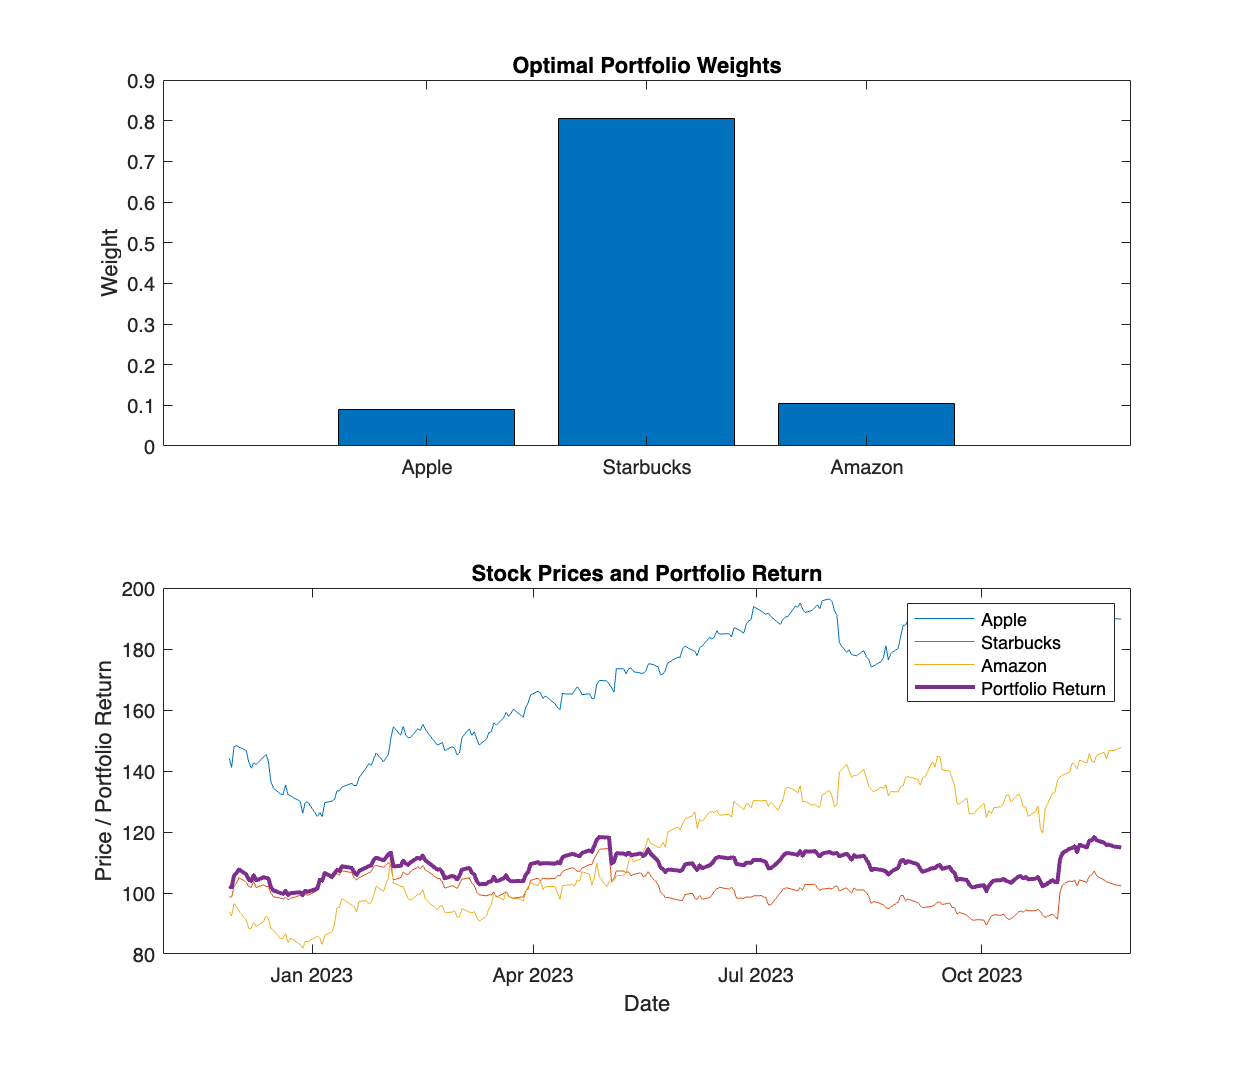

figure('Position', [350, 100, 700, 600]);

% Bar plot of optimal portfolio weights
subplot(2, 1, 1);
stock_labels = name_arr;
bar(best_solution);
xticklabels(stock_labels);
title('Optimal Portfolio Weights');
ylabel('Weight');

% Plot closing prices for each stock and the portfolio return
subplot(2, 1, 2);
for i = 1:numel(stockData)
    str = name_arr(i);
    plot(stockData{i}.Date, stockData{i}.Close, 'DisplayName', str);
    hold on;
end
portfolioReturn = closingPrices*best_solution';
plot(stockData{1}.Date, portfolioReturn, 'LineWidth', 2, 'DisplayName', 'Portfolio Return');
title('Stock Prices and Portfolio Return');
xlabel('Date');
ylabel('Price / Portfolio Return');
legend('show');

The plot should show above. Click the arrow in the upper right to open a separate MATLAB figure!

The original parameters tend to prioritize the most stable stock. Increase the penalty and/or decrease the max_weight for different results!

## Function Definitions

function result = myRosenbrock(x, y, a, b)
    result = (a - x).^2 + b * (y - x.^2).^2;
end

function result = AckleyFunction(x, y)
    result = -20 * exp(-0.2 * sqrt(0.5 * (x.^2 + y.^2))) - exp(0.5 * (cos(2 * pi * x) + cos(2 * pi * y))) + exp(1) + 20;
end

% ~ Generate new candidate food sources given a current location ~
function v_ij = produceCandidatePosition(x_ij, positions, i, D, phi)
% Implementing the formula: v_ij = x_ij + phi(x_ij - x_kj)

% Choose a random food source index k, different from i (the new food source
% must be different from the current one)
k = randi(size(positions, 1));
while k == i
    k = randi(size(positions, 1));
end

v_ij = zeros(1, D);
v_ij(1:D) = x_ij(1:D) + phi*(x_ij(1:D) - positions(k, 1:D));
end

% ~ Onlooker Bee Food Selection Routine ~
function index = onlookerSelectFoodSource(probabilities)
% Evaluate the nectar information of food sources found by employed bees
% based on the roulette wheel method. 
        % The roulette wheel method probabilistically selects an item from 
        % a set by duplicating each item proportional to its probability.

% Get the cumulative probabilities
cumulative_probs = cumsum(probabilities);

% Roll the roulette wheel
random_value = rand();
index = find(random_value <= cumulative_probs, 1);
end

% ~ New Food Source Generation ~
function food_positions = generateFoodSources(num_positions, lower_bound, upper_bound)
num_variables = numel(lower_bound);
food_positions = rand(num_positions, num_variables) .* (upper_bound - lower_bound) + lower_bound;
end

% ~ Define the Behavior of Employed Bees ~
function [new_positions, count_arr] = employedBeeRoutine_1(positions, count_arr, fitness, function_name, D, lower_bounds, upper_bounds)
% Employed Bees go to the food source of their previous cycle and choose a
% new food source.
for i = 1:size(positions, 1)
    % Revisit the food source from the previous cycle
    current_position = positions(i, :);

    % Choose a new food source from the surrounding landscape
    phi = -1+2*rand();
    new_position = produceCandidatePosition(current_position, positions, i, D, phi);
    new_fitness = function_name(new_position(:, 1), new_position(:, 2));

    % Check if the new position is better. If so, update it in the Bee's
    % memory. Otherwise, keep count of how many cycles the bee has been
    % stuck here.
    if new_fitness < fitness(i)
        % Ensure the new position is within range
        new_position = max(lower_bounds, min(upper_bounds, new_position));
        positions(i, :) = new_position;
        count_arr(i) = 0;
    else
        count_arr(i) = count_arr(i) + 1;
    end
end
new_positions = positions;
end

% ~ Define the Behavior of Onlooker Bees ~
function new_positions = onlookerBeeRoutine_1(onlooker_positions, onlooker_fitness, employed_positions, employed_fitness, function_name, D, lower_bounds, upper_bounds)
food_source_probability = employed_fitness/sum(employed_fitness);

new_positions = onlooker_positions;
for i = 1:size(new_positions, 1)
    % Select an employed food source based on probabilities
    index = onlookerSelectFoodSource(food_source_probability);

    % Find a new food source
    phi = -1+2*rand();
    new_position = produceCandidatePosition(employed_positions(index, :), ...
        employed_positions, i, D, phi);
    new_fitness = function_name(new_position(:, 1), new_position(:, 2));

    % If the new source is better, update the employed bee's position
    if new_fitness < employed_fitness(index)
        employed_positions(index, :) = new_position;
        employed_fitness(index) = new_fitness;
    end
    
    % Update the onlooker bee's position
    if isnan(new_positions(i, :))
        new_positions(i, :) = new_position;
    else
        % If the new source is better, update the onlooker bee
        if new_fitness < onlooker_fitness(index)
            % Ensure the new position is in the solution space
            new_position = max(lower_bounds, min(upper_bounds, new_position));
            new_positions(i, :) = new_position;
        end
    end
end
end

% ~ Define the Behavior of Scout Bees ~
function [updated_positions, employed_count_arr] = scoutBeeRoutine_1(employed_positions, employed_count_arr, lower_bounds, upper_bounds, limit)
    % Identify employed bees whose food sources have been exhausted
    exhausted_indices = employed_count_arr >= limit;
    fprintf('   %d abandoned food sources. \n', sum(exhausted_indices))

    if sum(exhausted_indices) ~= 0
        % Generate new positions for exhausted employed bees
        new_positions = employed_positions;
        new_positions(exhausted_indices, :) = generateFoodSources(sum(exhausted_indices), ...
            lower_bounds, upper_bounds);
    
        % Update positions and reset counters of exhausted employed bees
        employed_positions = new_positions;
        employed_count_arr(exhausted_indices) = 0;
    end
updated_positions = employed_positions;
end

%% Example 2 Functions 
% ~ Gomez and Levy Function
function result = GomezLevy_function(x, y)
    result = 4*x.^2 - 2.1*x.^4 + 1/3*x.^6 + x.*y -4*y.^2 + 4*y.^4;
end

% ~ Townsend Function ~
function result = MishraBF(x, y)
    result = sin(y) .* exp((1 - cos(x)).^2) + cos(x) .* exp((1 - sin(y)).^2) + (x - y).^2;
end

% ~ Constraint function for the Gomez and Levy Function ~
function result = constraint_function(x, y)
    % Constraint function:
    % -sin(4*pi*x) + 2 sin^2(2*pi*y) <= 1.5 

    % Note how we convert it to a function g(x, y) in the following line. 
    % If a solution satisfies the constraint, g(x, y) < 0. Otherwise, 
    % g(x, y) > 0. So by returning the maximum value of g(x, y) greater 
    % than zero we penalize solutions violating our constraint!
    g_value = -sin(4*pi*x) + 2*(sin(2*pi*y)).^2 - 1.5;

    % Penalty function: Add a penalty for positive values of g
    result = max(0, g_value);
end

function result = constraint_function_MBF(x, y)
    % Constraint function for Mishra's Bird Function
    % (x + 5).^2 + (y + 5).^2 < 25

    % Calculate the constraint
    g = (x + 5).^2 + (y + 5).^2 - 25;

    % Evaluate the constraint function
    result = max(0, g);
end

% ~ Return the fitness for a group of solutions ~
function fitness_values = evaluateFitnessGL(population)
    % Evaluate the objective function and apply penalty for constraints
    x_values = population(:, 1);
    y_values = population(:, 2);

    % Note how we're adding the constraint!
    fitness_values = GomezLevy_function(x_values, y_values) + ... 
        constraint_function(x_values, y_values);
end

% ~ Return the fitness for a group of solutions ~
function fitness_values = evaluateFitnessMBF(population)
    % Evaluate the objective function and apply penalty for constraints
    x_values = population(:, 1);
    y_values = population(:, 2);

    % Note how we're adding the constraint!
    fitness_values = MishraBF(x_values, y_values) + ... 
        constraint_function_MBF(x_values, y_values);
end

% ~ Vectorized Employed Bee Routine ~
function [new_positions, count_arr] = employedBeeRoutine_vectorized(positions, count_arr, fitness, evaluate_fitness_function, D, lower_bounds, upper_bounds)
    % Employed Bees go to the food source of their previous cycle and choose a
    % new food source.
    
    % Revisit the food sources from the previous cycle
    current_positions = positions;

    % Choose new food sources from the surrounding landscape
    phi = -1 + 2 * rand(size(fitness, 1), 1);
    new_positions = arrayfun(@(i) produceCandidatePosition(current_positions(i, :), current_positions, i, D, phi(i)), 1:size(fitness, 1), 'UniformOutput', false);
    new_positions = cat(1, new_positions{:});

    % Evaluate fitness for new positions
    new_fitness = evaluate_fitness_function(new_positions);

    % Find indices where new positions are better
    better_indices = new_fitness < fitness;

    % Update positions and count_arr accordingly
    positions(better_indices, :) = new_positions(better_indices, :);
    count_arr(better_indices) = 0;
    count_arr = count_arr + ~better_indices;

    % Ensure the updated positions are within bounds
    new_positions = max(lower_bounds, min(upper_bounds, positions));
end

% ~ Vectorized Onlooker Bee Routine ~
function new_positions = onlookerBeeRoutine_vectorized(onlooker_positions, onlooker_fitness, employed_positions, employed_fitness, evaluate_fitness_function, D, lower_bounds, upper_bounds)
    % Calculate the probabilities for each onlooker bee
    food_source_probability = employed_fitness / sum(employed_fitness);

    % Roll the roulette wheel to select indices for all onlooker bees at once
    selected_indices = arrayfun(@(p) onlookerSelectFoodSource(food_source_probability), 1:size(onlooker_fitness, 1), 'UniformOutput', false);
    selected_indices = cell2mat(selected_indices)';

    % Find new positions for all onlooker bees at once
    phi_values = -1 + 2 * rand(size(onlooker_fitness));
    new_positions = arrayfun(@(i) produceCandidatePosition(employed_positions(selected_indices(i), :), ...
        employed_positions, i, D, phi_values(i)), 1:size(onlooker_fitness, 1), 'UniformOutput', false);
    new_positions = cat(1, new_positions{:});
    new_fitness = evaluate_fitness_function(new_positions);

    % Update onlooker positions for selected indices
    update_condition = new_fitness < onlooker_fitness;
    new_positions(update_condition, :) = max(lower_bounds, min(upper_bounds, new_positions(update_condition, :)));
    onlooker_positions(update_condition, :) = new_positions(update_condition, :);

    new_positions = onlooker_positions;
end

%% Example 3 functions

% ~ New Food Source Generation ~
function food_positions = generateFoodSourcesStocks(num_positions, lower_bound, upper_bound)
num_variables = numel(lower_bound);
food_positions = rand(num_positions, num_variables) .* (upper_bound - lower_bound) + lower_bound;

% normalize these positions
food_positions = food_positions./sum(food_positions, 2);
end

% ~ Generate new candidate food sources given a current location ~
function v_ij = produceCandidatePositionStocks(x_ij, positions, i, D, phi)
    % Implementing the formula v_ij = x_ij + phi(x_ij - x_kj)

    % Choose a random food source index k different from i (the new food source
    % must be different from the current one)
    k = randi(size(positions, 1));
    while k == i
        k = randi(size(positions, 1));
    end

    % Calculate the candidate position
    v_ij = x_ij(1:D) + phi * (x_ij(1:D) - positions(k, 1:D));

    % Normalize
    v_ij = v_ij / sum(v_ij);
end

% ~ Define your objective function~
function result = SharpeRatio_function(x, closingPrices, max_weight, penalty_factor)
% SharpeRatio_function_with_penalty
% Formula:
%   result = [- mean_returns / std_returns ] / sqrt( 1 + penalty_term)
%
% Inputs:
%   x:                Portfolio weights for each asset
%   closingPrices:    Historical closing prices matrix
%   max_weight:       Maximum allowed weight for any individual asset
%   penalty_factor:   Factor controlling the strength of the penalty

Sharpe = -mean(closingPrices*x') / std(closingPrices*x');
% Calculate the penalty term for weights exceeding the max_weight
exceeding_weights = max(x - max_weight, 0);
penalty_term = penalty_factor * sum(exceeding_weights.^2);

result = Sharpe/sqrt(1 + penalty_term);
end

function fitness_values = evaluateFitnessStocks(employed_positions, closingPrices, max_weight, penalty_factor)
    num_solutions = size(employed_positions, 1);

    % Normalize weights for all solutions
    normalized_weights = employed_positions ./ sum(employed_positions, 2);

    % Calculate Sharpe ratios for all solutions
    sharpe_ratios = arrayfun(@(i) SharpeRatio_function(normalized_weights(i, :), closingPrices, max_weight, penalty_factor), 1:num_solutions);

    % Output the fitness values
    fitness_values = sharpe_ratios';
end

% ~ Vectorized Employed Bee Routine ~
function [new_positions, count_arr] = employedBeeRoutine_vectorized_Stocks(positions, count_arr, fitness, closing_prices, D, lower_bounds, upper_bounds, max_weight, penalty_factor)
    % Employed Bees go to the food source of their previous cycle and choose a
    % new food source.
    
    % Revisit the food sources from the previous cycle
    current_positions = positions;

    % Choose new food sources from the surrounding landscape
    phi = -1 + 2 * rand(size(fitness, 1), 1);
    new_positions = arrayfun(@(i) produceCandidatePositionStocks(current_positions(i, :), current_positions, i, D, phi(i)), 1:size(fitness, 1), 'UniformOutput', false);
    new_positions = cat(1, new_positions{:});

    % Evaluate fitness for new positions
    new_fitness = evaluateFitnessStocks(new_positions, closing_prices, max_weight,...
        penalty_factor);

    % Find indices where new positions are better
    better_indices = new_fitness < fitness;

    % Update positions and count_arr accordingly
    positions(better_indices, :) = new_positions(better_indices, :);
    count_arr(better_indices) = 0;
    count_arr = count_arr + ~better_indices;

    % Ensure the updated positions are within bounds
    new_positions = max(lower_bounds, min(upper_bounds, positions));
end

% ~ Vectorized Onlooker Bee Routine ~
function new_positions = onlookerBeeRoutine_vectorized_Stocks(onlooker_positions, onlooker_fitness, employed_positions, employed_fitness, closing_prices, D, lower_bounds, upper_bounds, max_weight, penalty_factor)
    % Calculate the probabilities for each onlooker bee
    food_source_probability = employed_fitness / sum(employed_fitness);

    % Roll the roulette wheel to select indices for all onlooker bees at once
    selected_indices = arrayfun(@(p) onlookerSelectFoodSource(food_source_probability), 1:size(onlooker_fitness, 1), 'UniformOutput', false);
    selected_indices = cell2mat(selected_indices)';

    % Find new positions for all onlooker bees at once
    phi_values = -1 + 2 * rand(size(onlooker_fitness));
    new_positions = arrayfun(@(i) produceCandidatePositionStocks(employed_positions(selected_indices(i), :), ...
        employed_positions, i, D, phi_values(i)), 1:size(onlooker_fitness, 1), 'UniformOutput', false);
    new_positions = cat(1, new_positions{:});
    new_fitness = evaluateFitnessStocks(new_positions, closing_prices, max_weight,...
        penalty_factor);

    % Update onlooker positions for selected indices
    update_condition = new_fitness < onlooker_fitness;
    new_positions(update_condition, :) = max(lower_bounds, min(upper_bounds, new_positions(update_condition, :)));
    onlooker_positions(update_condition, :) = new_positions(update_condition, :);

    new_positions = onlooker_positions;
end

% ~ Define the Behavior of Scout Bees ~
function [updated_positions, employed_count_arr] = scoutBeeRoutine_Stocks(employed_positions, employed_count_arr, lower_bounds, upper_bounds, limit)
    % Identify employed bees whose food sources have been exhausted
    exhausted_indices = employed_count_arr >= limit;
    fprintf('   %d abandoned food sources. \n', sum(exhausted_indices))

    if sum(exhausted_indices) ~= 0
        % Generate new positions for exhausted employed bees
        new_positions = employed_positions;
        new_positions(exhausted_indices, :) = generateFoodSourcesStocks(sum(exhausted_indices), ...
            lower_bounds, upper_bounds);
    
        % Update positions and reset counters of exhausted employed bees
        employed_positions = new_positions;
        employed_count_arr(exhausted_indices) = 0;
    end
updated_positions = employed_positions;
end